# **RT-QIBC analysis**

**FarRed1: Chromatin-bound RPA**

**YFP1: Chromatin-bound PCNA**

**POI(:,2): APC/C inactivation time**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';

%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
    'H2O/DMSO no dox',2:4,2,1:4,[0 0 0],'HU-','DMSO','Dox-'; %1
    'H2O/ATRi no dox',5:7,2,1:4,[0 0 0],'HU-','ATRi','Dox-'; %1
    
    'HU/DMSO no dox',2:4,3,1:4,[0 0 0],'HU+','DMSO','Dox-'; %1
    'HU/ATRi no dox',5:7,3,1:4,[0 0 0],'HU+','ATRi','Dox-'; %1
    
    'H2O/DMSO dox',2:4,4:6,1:4,[0 0 0],'HU-','DMSO','Dox+'; %1
    'H2O/ATRi dox',5:7,4:6,1:4,[0 0 0],'HU-','ATRi','Dox+'; %1
    
    'HU/DMSO dox',2:4,7:9,1:4,[0 0 0],'HU+','DMSO','Dox+'; %1
    'HU/ATRi dox',5:7,7:9,1:4,[0 0 0],'HU+','ATRi','Dox+'; %1
    };


load([dataDir filesep 'C150_data.mat'],'S');
% S = loadData_C150(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 69;
frameEdU = 0;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

**Compare dna**

conds = [5];

% yval = 'FarRed2';

data = {};

figure('Units', 'Inches', 'Position', [0, 0, 4, 2])

for i = 1:length(conds)
    condition = conds(i);
    ydata = (S(conds(i)).sigNuc(:,end)); %.*S(condition).area);

    
    ydata(ydata < .25) = [];
    ydata(ydata>2^10) = [];
    ydata = log2(ydata);
    
    data = [data, {ydata}];

end
nhist(data,'samebins','noerror','pdf','maxbins',50)

ans = 1×1 cell array
    {'Plot #1: '}


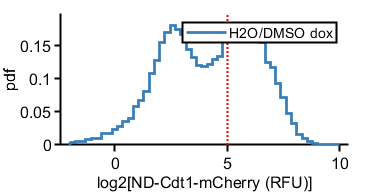

xlabel('log2[ND-Cdt1-mCherry (RFU)]')
legend(conditions(conds,1));
% axis square
vline([5])
print_pdf([pwd() '\Figs\cdt1hist.pdf'])

data

data = 1×1 cell array
    {33913×1 double}


**Set thresholds based on treatment 1**

cond = 1;
figure
xval = 'FarRed1';
yval = 'YFP1';

xdata = S(cond).(xval);
ydata = S(cond).(yval) ;

inds = log2(S(cond).dna) < 20.25 & S(cond).apcNuc(:,end) < 10 & ydata < 45;
xdata = xdata(inds);
ydata = ydata(inds);

% inds = xdata < prctile(xdata,95) & ydata < prctile(ydata,95);
% xdata = xdata(inds);
% ydata = ydata(inds);

RPAThresh = prctile(xdata,90)

RPAThresh = 132.4390

PCNAThresh = prctile(ydata,95)

PCNAThresh = 30.5936

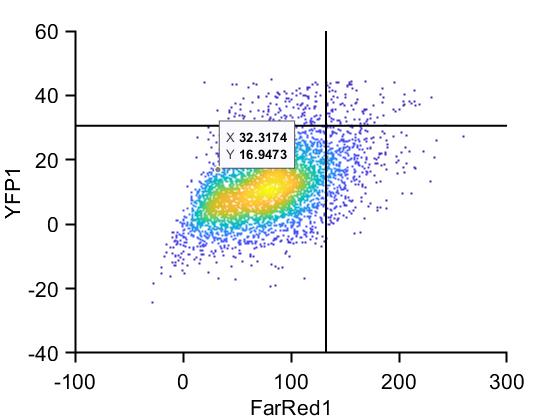



dscatter(xdata,ydata)
hline(PCNAThresh,'k');
vline(RPAThresh,'k');
ylabel(yval);xlabel(xval);

Settings thresholds based on 95% (with a removal of EdU positive cells by arb threshold)

**Load data into table**

conds=1:8;
poiAligned=2;
offset=0;

dfTotal = table();

gateVals = {{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};

for i=1:length(conds)
    ind = true(size(S(conds(i)).sigNuc(:,1))) ;
    
    time=(numFrames-(S(conds(i)).POI(ind,poiAligned)-offset))/framesPerHr;
    cdt1=(S(conds(i)).sigNuc(ind,end));
    PCNA=(S(conds(i)).YFP1(ind));
    RPA=(S(conds(i)).FarRed1(ind));
    
    
    gates = gateVals{i};
    for j=1:length(gates)
        %gateData = S(conds(i)).(gates{j})(ind);
        gateData = S(conds(i)).(gates{j})(ind,end);
        inds = gateData < rangeVals{i}{j}(2) & gateData > rangeVals{i}{j}(1);
        time = time(inds);
        cdt1 = cdt1(inds);
        PCNA = PCNA(inds);
        ydata3 = RPA(inds);
    end
    
        inds = time <= 3 & time >= 2 & PCNA > PCNAThresh;
    time = time(inds);
    cdt1 = cdt1(inds);
    PCNA = PCNA(inds);
    RPA = RPA(inds);
   
%     cdt1(cdt1<1) = 1;
%     PCNA(PCNA<1) = 1;
%     RPA(RPA<1) = 1;
    rpaNorm = RPA./PCNA;

    treatment = repmat(categorical(conditions(conds(i),1)),numel(time),1);
    HUtreatment = repmat(categorical(conditions(conds(i),6)),numel(time),1);
    ATRtreatment = repmat(categorical(conditions(conds(i),7)),numel(time),1);
    doxTreatment = repmat(categorical(conditions(conds(i),8)),numel(time),1);
    
    dfTotal = [dfTotal;table(treatment, HUtreatment, ATRtreatment, doxTreatment,time,cdt1,PCNA,RPA,rpaNorm)];
end

Unrecognized function or variable 'PCNAThresh'.


dfTotal.drugTreatment = categorical(strcat(string(dfTotal.HUtreatment),{'\'},string(dfTotal.ATRtreatment)));
dfTotal = movevars(dfTotal,'drugTreatment','After','doxTreatment');

conds = [1];
for i=1:length(conds)
    
    ind = log2(S(conds(i)).dna) < 20.25 & S(conds(i)).apcNuc(:,end) < 10 & S(conds(i)).YFP1 < 50;
    cdt1=(S(conds(i)).sigNuc(ind,end));
    PCNA=(S(conds(i)).YFP1(ind));
    RPA=(S(conds(i)).FarRed1(ind));
    
    ind = randsample(length(cdt1),300);
    cdt1=cdt1(ind);
    PCNA=PCNA(ind);
    RPA=RPA(ind);
    
%     cdt1(cdt1<0.0001) = 1;
%     PCNA(PCNA<0.0001) = 1;
%     RPA(RPA<0.0001) = 1;
    rpaNorm = RPA./PCNA;
    
    time = repmat(0,numel(cdt1),1);
    treatment = repmat(categorical(cellstr('G1')),numel(cdt1),1);
    HUtreatment = repmat(categorical(cellstr('G1')),numel(cdt1),1);
    ATRtreatment = repmat(categorical(cellstr('G1')),numel(cdt1),1);
    doxTreatment = repmat(categorical(cellstr('G1')),numel(cdt1),1);
    drugTreatment = repmat(categorical(cellstr('G1')),numel(cdt1),1);
    dfTotal = [dfTotal; table(treatment, HUtreatment, ATRtreatment, doxTreatment,drugTreatment,time,cdt1,PCNA,RPA,rpaNorm)];
end

Subset based on cdt1 expression

dfGated = dfTotal((log2(dfTotal.cdt1) > 5 & dfTotal.doxTreatment == 'Dox+') |...
    dfTotal.doxTreatment == 'Dox-' | dfTotal.treatment =='G1',:);

g= gramm('x',log2(dfGated.cdt1),'color',dfGated.doxTreatment);
g.stat_bin('geom','stairs','fill','transparent','normalization','pdf');
figure,
g.draw();

order = {'G1','H2O/DMSO no dox','H2O/DMSO dox','HU/DMSO no dox','HU/DMSO dox','HU/ATRi no dox','HU/ATRi dox',};
ally = [];
group = [];
rng(1)
for i=1:length(order)
    inds = dfGated.treatment == order{i};
    data = (dfGated.RPA(inds));

    ally = [ally; data];
    group = [group; i*ones(length(data),1)];
    n(i) = length(data);
end
group_list = 1:max(group)+1;
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list(1:end-1) + offsetx(2:end);
n'

ans =    300
   281
   392
   284
   389
   182
   240


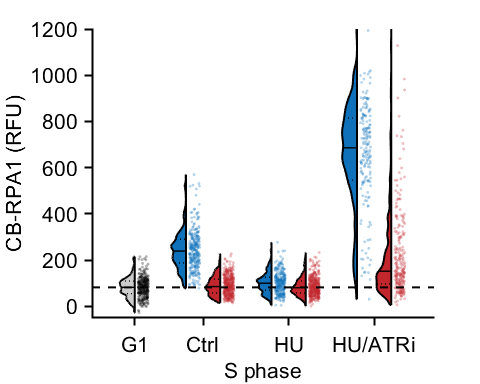

figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.7,'xValues',xkey,'widthDiv',[2 1],...
    'xNames',order);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
cols = [14 113 186; 193 39 45]/255;
groupcol = [0 0 0; cols([1 2 1 2 1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 5,groupcol(group,:),'filled','MarkerFaceAlpha',.3);
ylabel('CB-RPA1 (RFU)')
ylim([-50 1200])
xticks([1 xkey(2:2:length(xkey)-1)+.5])
xticklabels({'G1','Ctrl','HU','HU/ATRi'})
xlabel('S phase')
% xtickangle(45)
hline(median(dfGated.RPA(dfGated.treatment == 'G1')),'k--')
% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\RPAcompare.pdf'])

order = {'G1','H2O/DMSO no dox','H2O/DMSO dox','HU/ATRi no dox','HU/ATRi dox',};
ally = [];
group = [];
rng(1)
for i=1:length(order)
    inds = dfGated.treatment == order{i};

    data = (dfGated.RPA(inds));

    ally = [ally; data];
    group = [group; i*ones(length(data),1)];
    n(i) = length(data);
end
group_list = 1:max(group)+1;
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list(1:end-1) + offsetx(2:end);
n'

ans =    300
   281
   392
   182
   240
   182
   240


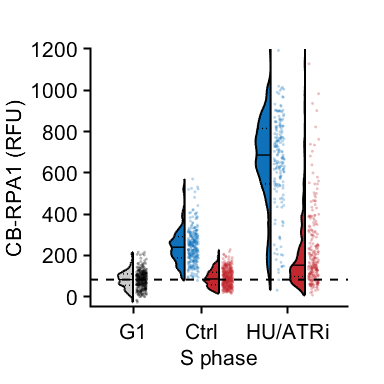

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.7,'xValues',xkey,'widthDiv',[2 1],...
    'xNames',order);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
cols = [14 113 186; 193 39 45]/255;
groupcol = [0 0 0; cols([1 2 1 2 1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 5,groupcol(group,:),'filled','MarkerFaceAlpha',.3);
ylabel('CB-RPA1 (RFU)')
ylim([-50 1200])
xticks([1 xkey(2:2:length(xkey)-1)+.5])
xticklabels({'G1','Ctrl','HU/ATRi'})
xlabel('S phase')
axis square
% xtickangle(45)
hline(median(dfGated.RPA(dfGated.treatment == 'G1')),'k--')
% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\RPAcompare_noHU.pdf'])

order = {'G1','H2O/DMSO no dox','H2O/DMSO dox','HU/DMSO no dox','HU/DMSO dox','HU/ATRi no dox','HU/ATRi dox',};
ally = [];
group = [];
rng(1)
for i=1:length(order)
    inds = dfGated.treatment == order{i};

    data = (dfGated.PCNA(inds));

    ally = [ally; data];
    group = [group; i*ones(length(data),1)];
    n(i) = length(data);
end
group_list = 1:max(group)+1;
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list(1:end-1) + offsetx(2:end);
n'

ans =    300
   281
   392
   284
   389
   182
   240


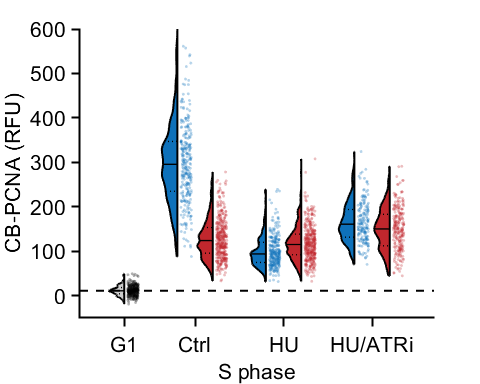

figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.7,'xValues',xkey,'widthDiv',[2 1],...
    'xNames',order);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
cols = [14 113 186; 193 39 45]/255;
groupcol = [0 0 0; cols([1 2 1 2 1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 5,groupcol(group,:),'filled','MarkerFaceAlpha',.3);
ylabel('CB-PCNA (RFU)')
ylim([-50 600])
xticks([1 xkey(2:2:length(xkey)-1)+.5])
xticklabels({'G1','Ctrl','HU','HU/ATRi'})
xlabel('S phase')
% xtickangle(45)
hline(median(dfGated.PCNA(dfGated.treatment == 'G1')),'k--')
% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\PCNAcompare.pdf'])